# Geostatistika: zápočtový příklad 

## Načtení zkušebních dat

Mejmě zkušební data definující hodnoty nějaké veličiny v ploše. Načteme si je proměnných  `xd`, `yd` reprezentující jednotlivé souřadnice a `zd` pro danu hodnotu proměnné `z = z(x, y)`.

[xd, yd, zd] = data();

## Základní analýza dat

#### Popisná statistika dat

Pro načetné hodnoty si můžeme vypsat vybrané popisné charakteristiky dat jako minimum, maximum, průměr, medián.

min(zd)

ans = 4.4000

max(zd)

ans = 94

mean(zd)

ans = 13.2295

median(zd)

ans = 12.9000

Histogram a krabicový  plot nám ukáže základní rozdělení dat.

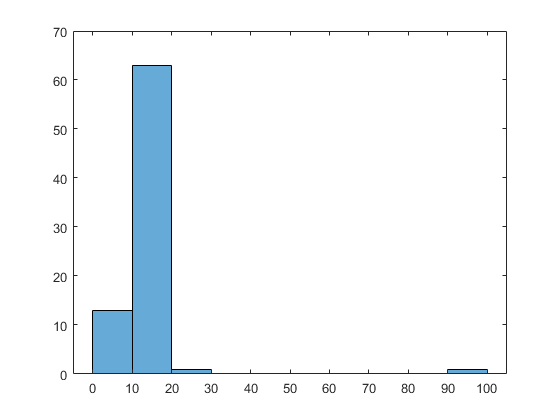

histogram(zd)

boxplot(zd)

Trend

% Parametry mřížky.
xg = [0:5:200];
yg = [0:5:200];

% trend2D(xd, yd, zd, xg, yg, 1, 1000) % Tady mi přestal fungovat Toolbox...

### Variogram

Variogram funkce exponeciální s dosahem 50 a prahem 8.

vario = '8 * (1 - exp(-(3 * h / 50)))';
variogram2D(xd, yd, zd, 20, 150, vario)
close all;

Variogram funkce sférický s dosahem 50 a prahem 8.

vario = '(heaviside(h) - heaviside(-h)) * 0.5 + 8 * (3/2 * min(h,50) / 50 - 1/2 * min(h,50).^3/50^3)';
variogram2D(xd, yd, zd, 20, 150, vario)
close all;

### Krigging

Kriging s nugget efektem = 0.5 a chybou = 1 a exponenciálním variogramem.

close all;
vario = '8 * (1 - exp(-(3 * h / 50)))';
krigging2D(xd, yd, zd, xg, yg, vario, 0.5, 1);

nx = 1681

close all;


Kriging s nugget efektem = 0.5 a chybou = 1 a sférickým variogramem.

close all;
vario = '(heaviside(h) - heaviside(-h)) * 0.5 + 8 * (3/2 * min(h,50) / 50 - 1/2 * min(h,50).^3/50^3)';
krigging2D(xd, yd, zd, xg, yg, vario, 0.5, 1);

nx = 1681

close all;